# **DANE**

## Skrzydło

clear sum
clear all
cr = 33.3; %[ft]
ct = 6.5; %[ft]
b = 156.1; %[ft]
lambda_w=ct/cr;
l_cg = 73.3

l_cg = 73.3000

AR = 7.844;    
b=156.1; %[ft]
Lambda_LE=34; %[deg]
Lambda_LE_rad = deg2rad(Lambda_LE);
MAC = 22.9; %[ft]
S = 3106; %[ft^2]
y_MAC = 30.266; %[ft]
x_MAC = 20.414; %[ft]
Lambda_025 = 30.484; %[deg]
Lambda_025_rad = deg2rad(Lambda_025); %[rad]
Lambda_05 = 26.694; %[deg]
Lambda_05_rad = deg2rad(Lambda_05); %[rad]

## Usterzenie poziome

lambda_H = 0.311;
AR_H = 5.267;
b_H = 61.1; %[ft]
Lambda_LEH = 38; %[deg]
Lambda_LEH_rad = deg2rad(Lambda_LEH); %[rad]
MAC_H = 12.669; %[ft]
S_H = 708.760; %[ft^2]
y_MAC_H = 12.597; %[ft]
x_MAC_H = 9.842; %[ft]
Lambda_025H = 34.272; %[deg]
Lambda_025H_rad = deg2rad(Lambda_025H); %[rad]
Lambda_05H = 30.183; %[deg]
Lambda_05H_rad = deg2rad(Lambda_05H); %[rad]

## Usterzenie pionowe

lambda_V = 0.323;
AR_V = 3.846;
b_V = 29.9; %[ft]
Lambda_LEV = 45; %[deg]
Lambda_LEV_rad = deg2rad(Lambda_LEV);
MAC_V = 16.905; %[ft]
S_V = 464.945; %[ft^2]
y_MAC_V = 12.402; %[ft]
x_MAC_V = 12.402; %[ft]
Lambda_025V = 40.927; %[deg]
Lambda_025V_rad = deg2rad(Lambda_025V); %[rad]
Lambda_05V = 36.283; %[deg]
Lambda_05V_rad = deg2rad(Lambda_05V); %[rad]

## Dane lotu

- dla dwóch wysokosći

- dla czterech prędkości

height = [0., 20000.]; %[ft]
mach = [0., 0.4, 0.5, 0.6]; %UWAGA CZTERY PREDKOŚCI

## Dane środowiskowe

temperature = [288.15 248.526]; %[K]
pressure = [2116.23 972.499]; %[lbf/ft^2]
density = [0.00237717, 0.00126659]; %[slug/ft^3]
v_sound = [1113.45, 1036.85]; %[ft/s]
dynamic_visosity = [3.78456E-07, 3.35735E-07]; %[slug/(ft*s)]
gravity_acceleration = [32.17, 32.17]; %[ft/s^2]
dyn_press_help1 = [v_sound.' v_sound.' v_sound.' v_sound.'].*[mach; %v_sound *mach
                                                              mach];
Vp1= dyn_press_help1;
dynamic_pressure = 0.5*[density.' density.' density.' density.'].*dyn_press_help1.*dyn_press_help1 %[lbf/ft^2]

dynamic_pressure =          0  235.7717  368.3933  530.4863
         0  108.9326  170.2072  245.0984


% dynamic_pressure = 0.5*density*(mach.*v_sound).^2 %[lbf/ft^2] ?

## Dane masowe

Weight = 270000; %[lbf]
Ixx = 4533982; %[slug*ft2]
Iyy = 7699141;   %[slug*ft2] 
Izz12 = 12090750; %[slug*ft2]
Ixz = 1094574; %[slug*ft2]
Mass = 8391,856431; %[slug]

Mass = 8391


L = 155; %[ft]

## Dane lotu z suplementu Żugaja

alfa_0 = -1.4; %deg
alfa_0_rad = deg2rad(alfa_0); %rad

Eps_0 = 0;
Eps_w = 2; %deg <--- podstawiasz w stopniach

e_os = 0.8;
C_L_0H = 0;

a_0w = -1.4; %[deg]  czy tu w stopniach????

eta_H = 0.85;
eta_v = 0.8;
eta_w = 0.8;

f = 35; %[ft^2]

i_H1 = 0; %[deg] [rad]

C_Du = 0;

## Inne dane geometryczne

x_WHR = 79.6 % [ft]

x_WHR = 79.6000

x_CG = 0.25*MAC % [ft]

x_CG = 5.7250

# **OBLICZENIA**

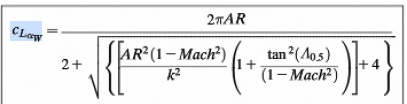 ale jeszcze razy eta_w!!!!!!!!

k = 1 + ((8.2 - 2.3*Lambda_LE_rad)-AR*(0.22 - 0.153*Lambda_LE_rad))/100

k = 1.0582


p1 = ((AR^2)*(1-mach.*mach))/(k^2)

p1 =    54.9447   46.1536   41.2086   35.1646


p2 = 1 + (tan(Lambda_05_rad)^2)./(1-mach.*mach)

p2 =     1.2528    1.3010    1.3371    1.3950




C_LaW = eta_w*(2*pi*AR)./(2+sqrt(4+p1.*p2))

C_LaW =     3.7428    3.9417    4.0700    4.2469


#### CLalfaH

k_H = 1+((8.2-2.3*Lambda_LEH_rad)-AR_H*(0.22-0.153*Lambda_LEH_rad))/100

k_H = 1.0605


C_LaH = eta_H*(2.*pi.*AR_H./(2+sqrt(AR_H^2.*(1-mach.^2)./k_H^2.*(1+tan(Lambda_05H_rad)^2./(1-mach.^2))+4)))

C_LaH =     3.4798    3.6296    3.7239    3.8513


# 

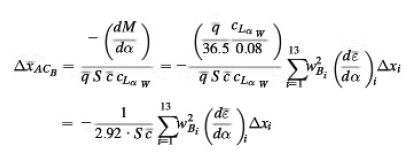

%%%%%%%%   d X_AC_B_dash   %%%%%%%%%%%%
pomoc1 = -1/(2.92*S*MAC)

pomoc1 = -4.8148e-06


%%%% GIGA SUMA
xh = 59.3093 %[ft]

xh = 59.3093


xi = [47.33 47.33 47.33 47.33;
      36.75 36.75 36.75 36.75;
      26.25 26.25 26.25 26.25;
      15.75 15.75 15.75 15.75;
      5.25 5.25 5.25 5.25;
      24.91 24.91 24.91 24.91;
      8.3 8.3 8.3 8.3;
      5.75 5.75 5.75 5.75;
      17.25 17.25 17.25 17.25;
      28.75 28.75 28.75 28.75;
      40.25 40.25 40.25 40.25;
      51.75 51.75 51.75 51.75;
      63.3 63.3 63.3 63.3]

xi =    47.3300   47.3300   47.3300   47.3300
   36.7500   36.7500   36.7500   36.7500
   26.2500   26.2500   26.2500   26.2500
   15.7500   15.7500   15.7500   15.7500
    5.2500    5.2500    5.2500    5.2500
   24.9100   24.9100   24.9100   24.9100
    8.3000    8.3000    8.3000    8.3000
    5.7500    5.7500    5.7500    5.7500
   17.2500   17.2500   17.2500   17.2500
   28.7500   28.7500   28.7500   28.7500


     
wbi = [8.4 8.4 8.4 8.4;
       14.84 14.84 14.84 14.84;
       16.45 16.45 16.45 16.45;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.28 16.28 16.28 16.28;
       14.19 14.19 14.19 14.19;
       9.64 9.64 9.64 9.64;
       5.18 5.18 5.18 5.18]

wbi =     8.4000    8.4000    8.4000    8.4000
   14.8400   14.8400   14.8400   14.8400
   16.4500   16.4500   16.4500   16.4500
   16.4600   16.4600   16.4600   16.4600
   16.4600   16.4600   16.4600   16.4600
   16.4600   16.4600   16.4600   16.4600
   16.4600   16.4600   16.4600   16.4600
   16.4600   16.4600   16.4600   16.4600
   16.4600   16.4600   16.4600   16.4600
   16.2800   16.2800   16.2800   16.2800



dxi = [10.66 10.66 10.66 10.66;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       16.6 16.6 16.6 16.6;
       16.6 16.6 16.6 16.6;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.63 11.63 11.63 11.63]

dxi =    10.6600   10.6600   10.6600   10.6600
   10.5000   10.5000   10.5000   10.5000
   10.5000   10.5000   10.5000   10.5000
   10.5000   10.5000   10.5000   10.5000
   10.5000   10.5000   10.5000   10.5000
   16.6000   16.6000   16.6000   16.6000
   16.6000   16.6000   16.6000   16.6000
   11.5000   11.5000   11.5000   11.5000
   11.5000   11.5000   11.5000   11.5000
   11.5000   11.5000   11.5000   11.5000


x_cf = xi/ cr

x_cf =     1.4213    1.4213    1.4213    1.4213
    1.1036    1.1036    1.1036    1.1036
    0.7883    0.7883    0.7883    0.7883
    0.4730    0.4730    0.4730    0.4730
    0.1577    0.1577    0.1577    0.1577
    0.7480    0.7480    0.7480    0.7480
    0.2492    0.2492    0.2492    0.2492
    0.1727    0.1727    0.1727    0.1727
    0.5180    0.5180    0.5180    0.5180
    0.8634    0.8634    0.8634    0.8634


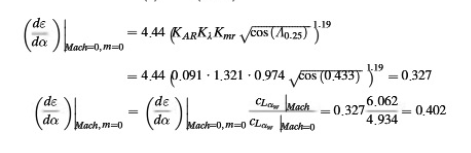

K_AR = (1/AR)-1/(1+AR^1.7)

K_AR = 0.0982

K_lambda = (10 - 3*lambda_w)/7

K_lambda = 1.3449


z_WH = 6.6 %[ft]

z_WH = 6.6000

m = 2* z_WH/b

m = 0.0846


x_WH = 75.7 %[ft]

x_WH = 75.7000

r = 2 * x_WH/b

r = 0.9699

K_mr0 = (1-0.5*0)/(r^0.33) %m=0 !!!!!!!!!

K_mr0 = 1.0101

K_mr = (1 - 0.5*m)/(r^0.33)

K_mr = 0.9674


dEps_da_Mach0_m0 = 4.44*(K_mr0*K_lambda*K_AR*sqrt(cos(Lambda_025_rad)))^1.19

dEps_da_Mach0_m0 = 0.3698


dEps_da_m0 = dEps_da_Mach0_m0*C_LaW/C_LaW(1)

dEps_da_m0 =     0.3698    0.3895    0.4022    0.4197



dEps_da = [1.11 1.11 1.11 1.11;
           1.16 1.16 1.16 1.16;
           1.24 1.24 1.24 1.24;
           1.405 1.405 1.405 1.405;
           3.86 3.86 3.86 3.86
           ]

dEps_da =     1.1100    1.1100    1.1100    1.1100
    1.1600    1.1600    1.1600    1.1600
    1.2400    1.2400    1.2400    1.2400
    1.4050    1.4050    1.4050    1.4050
    3.8600    3.8600    3.8600    3.8600


for i=6:13
    dEps_da = [dEps_da; (xi(i, :)/xh).*(1-dEps_da_m0)];
end


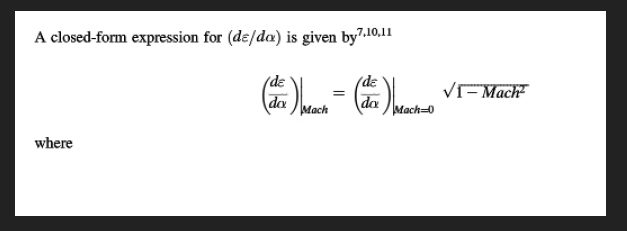

%%%%%% dEps_da_Mach
%dEps_da_Mach =(4.44*(K_mr*K_lambda*K_AR*sqrt(cos(Lambda_025_rad)))^1.19)*sqrt(1 -mach.*mach)
%ten wzór podobno fu

%%Powodowało błędy zmniłem na logikę
%dEps_da_Mach  = dEps_da_Mach(1)*C_LaW/C_LaW(1)

%%
dEps_da_Mach = dEps_da_m0.*sqrt(1 -mach.*mach)

dEps_da_Mach =     0.3698    0.3570    0.3483    0.3357


X_AC

%%%%%%%%   X_AC_W   %%%%%%%%%%%%
K1 = 1.45

K1 = 1.4500

K2 = 0.57865

K2 = 0.5786


p3 = [0.815 0.79 0.76 0.73] %X_AC/C_R z wykresu 2.27

p3 =     0.8150    0.7900    0.7600    0.7300



x_AC_W = K1.*(p3 - K2)

x_AC_W =     0.3427    0.3065    0.2630    0.2195



%%%%%% d_X_AC_B ostatecznie %%%%%%
d_X_AC_B = pomoc1*sum(wbi.*wbi.*dEps_da.*dxi)

d_X_AC_B =    -0.1304   -0.1297   -0.1292   -0.1285




x_AC_WB = x_AC_W + d_X_AC_B

x_AC_WB =     0.2123    0.1768    0.1338    0.0910




%%%%%% Dziki wzór Janeczka %%%%%%%%%
x_AC_H =x_WHR + x_MAC_H + (MAC_H/4) - x_MAC

x_AC_H = 72.1952

random_zmienna_pomocnicza = C_LaH./C_LaW.*eta_H* S_H/S.*(1-dEps_da_Mach)

random_zmienna_pomocnicza =     0.1136    0.1148    0.1157    0.1168


x_AC = (x_AC_WB + random_zmienna_pomocnicza.*x_AC_H)./(1+random_zmienna_pomocnicza)

x_AC =     7.5577    7.5957    7.6044    7.6345




x_AC_dash = x_AC/MAC

x_AC_dash =     0.3300    0.3317    0.3321    0.3334


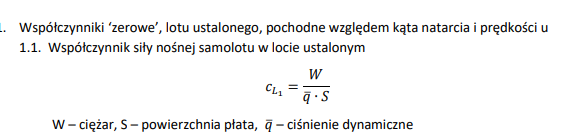

C_L1 = Weight./(dynamic_pressure*S)

C_L1 =        Inf    0.3687    0.2360    0.1639
       Inf    0.7980    0.5107    0.3547


C_La=C_LaW + C_LaH.*eta_H*(S_H/S).*(1-dEps_da_Mach)

C_La =     4.1681    4.3944    4.5407    4.7431


**Epsilon:**

Nie mogę znaleźć wzorów ale wierzę, że Michał to dobrze wpisał:

Wzór jest przepisany z czyjejś formuły w Excelu XDD \Michał

Eps = dEps_da_Mach.*(C_L1 - (-0.024))./(C_La)

Eps =        Inf    0.0319    0.0199    0.0133
       Inf    0.0668    0.0410    0.0268


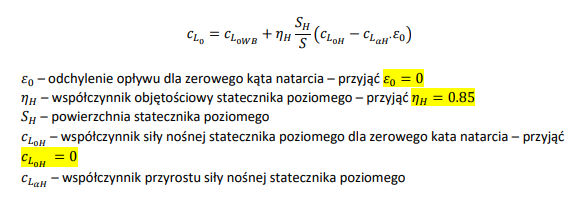

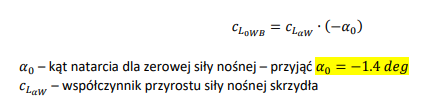

C_L0WB = C_LaW * (-alfa_0_rad)

C_L0WB =     0.0915    0.0963    0.0994    0.1038


C_L0 = C_L0WB + eta_H * (S_H/S) * (C_L_0H - C_LaH*Eps_0)

C_L0 =     0.0915    0.0963    0.0994    0.1038


mach_pom = [mach;
            mach]

mach_pom =          0    0.4000    0.5000    0.6000
         0    0.4000    0.5000    0.6000


C_Lu = ((mach_pom.*mach_pom)./(1-(mach_pom.*mach_pom))).*C_L1 %poprawione :)

C_Lu =        NaN    0.0702    0.0787    0.0922
       NaN    0.1520    0.1702    0.1995


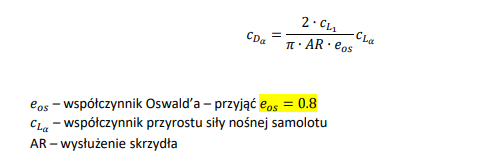

C_Da = ((2*C_L1)./(pi()*AR*e_os)).*C_La

C_Da =        Inf    0.1644    0.1087    0.0789
       Inf    0.3558    0.2353    0.1707


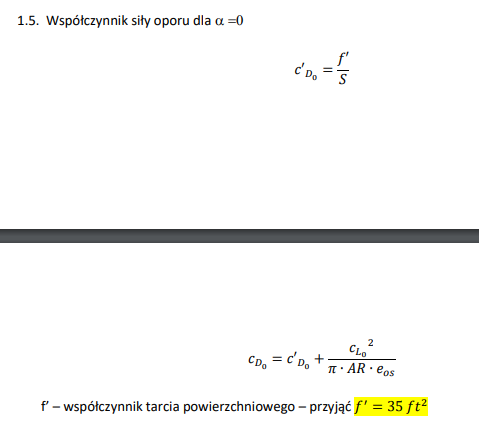

C_D0_pochodna = f/S

C_D0_pochodna = 0.0113

C_D0 = ((C_L0.*C_L0)/(pi()*AR*e_os)) + C_D0_pochodna

C_D0 =     0.0117    0.0117    0.0118    0.0118


**C_m0W**

cm0r = 0

cm0r = 0

cm0t = 0

cm0t = 0

d_Cm0_Eps_w = -0.00577 %powinien być na minusie???????????????

d_Cm0_Eps_w = -0.0058

C_m0W = ((AR*cos(Lambda_025_rad)^2)/(AR+2*cos(Lambda_025_rad)^2))*((cm0r+cm0t)/2)+(d_Cm0_Eps_w)*Eps_w

C_m0W = -0.0115

**C_m0B**

k2_k1 = 0.92355

k2_k1 = 0.9235

i_cl = [-6.33 -0.846 0.289 0 0 0 0 0 -0.633 -3.79 -3.638 -1.927 -1.379]

i_cl =    -6.3300   -0.8460    0.2890         0         0         0         0         0   -0.6330   -3.7900   -3.6380   -1.9270   -1.3790


C_m0B = (k2_k1/(36.5*S*MAC))*sum(wbi(:, 1).*wbi(:, 1).*(a_0w+i_cl.').*dxi()) %czy tu ma być w stopniach?????

C_m0B =    -0.0275   -0.0275   -0.0275   -0.0275


**C_m0WB**

C_m0_ratio = [1 1.03074 1.0715 1.12919]

C_m0_ratio =     1.0000    1.0307    1.0715    1.1292


C_m0_WB = (C_m0B+C_m0W).*C_m0_ratio

C_m0_WB =    -0.0390   -0.0402   -0.0418   -0.0441


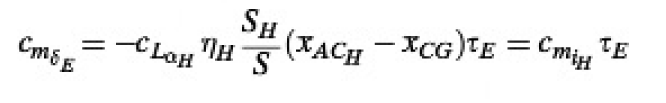

tau_e = 0.38 %fig 3.7

tau_e = 0.3800

x_AC_H_dash = x_AC_H/MAC

x_AC_H_dash = 3.1526

x_CG_dash = x_CG/MAC

x_CG_dash = 0.2500


C_mdelta_E = -C_LaH*eta_H*(S_H/S)*(x_AC_H_dash - x_CG_dash)*tau_e

C_mdelta_E =    -0.7445   -0.7765   -0.7967   -0.8240


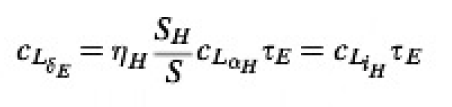

c_Ldelta_E = eta_H*(S_H/S)*C_LaH*tau_e

c_Ldelta_E =     0.2565    0.2675    0.2745    0.2839


**C_LiH**

C_LiH = eta_H*(S_H/S).*C_LaH

C_LiH =     0.6750    0.7040    0.7223    0.7470


**C_LWB**

C_L_WB = C_LaW*(-alfa_0_rad)

C_L_WB =     0.0915    0.0963    0.0994    0.1038


**C_Lq**

B= sqrt(1-mach.*mach.*(cos(Lambda_025_rad)^2))

B =     1.0000    0.9387    0.9024    0.8559


C_LqW_Mach0 = (0.5 +2* abs(x_AC_W-x_CG_dash))*C_LaW(1)

C_LqW_Mach0 =     2.5654    2.2940    1.9684    2.1000


C_LqW = (((AR + 2*cos(Lambda_025_rad))./(AR*B+2*cos(Lambda_025_rad)))).* C_LqW_Mach0

C_LqW =     2.5654    2.4154    2.1396    2.3813



C_LqH = 2 * C_LaH * eta_H * (S_H/S)*(x_AC_H_dash - x_CG_dash)

C_LqH =     3.9183    4.0869    4.1931    4.3366



C_Lq = C_LqW+C_LqH

C_Lq =     6.4837    6.5023    6.3327    6.7179


**C_m0**

C_m0 = C_m0_WB + (x_CG_dash-x_AC_WB).*(C_L_WB) % wyszły ujemne, nie wiem czy git

C_m0 =    -0.0356   -0.0332   -0.0303   -0.0276


**C_ma**

C_ma = C_LaW.*(x_CG_dash-x_AC_WB)-C_LaH*eta_H*(S_H/S).*(1-dEps_da_Mach).*(x_AC_H_dash-x_CG_dash)

C_ma =    -1.0935   -1.0255   -0.8934   -0.7650


**C_mu**

%dx_AC_w_dMach = -0.435 %h = 0 i h = 20000 dla obu jest tyle samo!!!!

dx_AC_w_dMach=K1.*p3./MAC

dx_AC_w_dMach =     0.0516    0.0500    0.0481    0.0462


C_mu = -C_L1.*dx_AC_w_dMach

C_mu =       -Inf   -0.0184   -0.0114   -0.0076
      -Inf   -0.0399   -0.0246   -0.0164


**C_m_alpha_dot**

C_m_alpha_dot = -2* C_LaH *(S_H/S)*((x_AC_H_dash-x_CG_dash)^2).*dEps_da_Mach

C_m_alpha_dot =    -4.9486   -4.9820   -4.9871   -4.9717


**C_miH**

C_miH = -C_LaH*eta_H*(S_H/S)*(x_AC_H_dash-x_CG_dash)

C_miH =    -1.9591   -2.0434   -2.0966   -2.1683


**C_Dq**

C_Dq = 0

C_Dq = 0

**C_m_qW**

C  = ((AR*(0.5*abs(x_AC_W - x_CG_dash)+2*abs(x_AC_W-x_CG_dash).^2))./(AR+2*cos(Lambda_025_rad)))+(1/24)*(((AR^3)*tan(Lambda_025_rad).^2)./(AR+6*cos(Lambda_025_rad)))+1/8

C =     0.7125    0.6888    0.6660    0.6745


Kq = 0.78

Kq = 0.7800

C_mqW_mach0 = - Kq *C_LaW(1)*cos(Lambda_025_rad)*C

C_mqW_mach0 =    -1.7926   -1.7329   -1.6756   -1.6969


pomoc2 = ((AR^3)*tan(Lambda_025_rad)^2)./(AR.*B+6*cos(Lambda_025_rad))

pomoc2 =    12.8506   13.3435   13.6537   14.0724


pomoc3 = ((AR^3)*tan(Lambda_025_rad)^2)/(AR+6*cos(Lambda_025_rad))

pomoc3 = 12.8506

C_mqW = ((pomoc2+(3./B))./(pomoc3+3)).*C_mqW_mach0

C_mqW = 1×4
   -1.7926   -1.8082   -1.7948   -1.8818


**C_m_qH**

C_m_qH = -2*C_LaH*eta_H*(S_H/S).*(x_AC_H_dash-x_CG_dash).*(x_AC_H_dash-x_CG_dash)

C_m_qH = 1×4
  -11.3733  -11.8627  -12.1712  -12.5876


**C_mq**

C_mq = C_mqW+C_m_qH

C_mq = 1×4
  -13.1660  -13.6710  -13.9660  -14.4694


**C_La_dot**

C_La_dot = 2*C_LaH.*eta_H.*(S_H/S).*(x_AC_H_dash-x_CG_dash).*dEps_da_Mach

C_La_dot = 1×4
    1.4491    1.4589    1.4604    1.4559


**alfa_1**

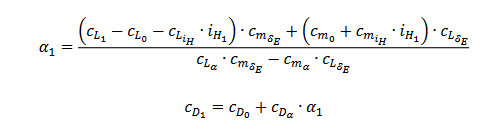

alfa_1 = ((C_L1-[C_L0; C_L0]).*[C_mdelta_E; C_mdelta_E]+([C_m0; C_m0]).*[c_Ldelta_E; c_Ldelta_E])./([C_La; C_La].*[C_mdelta_E; C_mdelta_E] - [C_ma; C_ma].*[c_Ldelta_E; c_Ldelta_E]) %pls spojrz na to czy ok - według mnie ok ~ Łukasz %na wszelki wszystkie macierze zrobiłem piętrowe, w jednym miejscu miało to akurat znaczenie ~ Michał

alfa_1 = 2×4
       Inf    0.0702    0.0347    0.0155
       Inf    0.1765    0.0996    0.0581


**C_D1**

C_D1 = C_D0 + C_Da.*alfa_1

C_D1 = 2×4
       Inf    0.0233    0.0155    0.0130
       Inf    0.0745    0.0352    0.0217


**delta_E1**

delta_E1 = (-(C_L1-[C_L0; C_L0]).*[C_ma; C_ma]-([C_m0; C_m0]).*[C_La; C_La])./([C_La; C_La].*[C_mdelta_E; C_mdelta_E]-[C_ma; C_ma].*[c_Ldelta_E; c_Ldelta_E])

delta_E1 = 2×4
      -Inf   -0.1355   -0.0769   -0.0479
      -Inf   -0.2758   -0.1497   -0.0875


## Zapisywanie danych do pliku .mat

Celem tego jest stworzenie później pliku .mat, by do kolejnego pliku załdować do workspace-u tylko potrzebne dane. Wpisałem tu wszystkie dane, które są w Excelu, i mam nadzieję, że się wszystkie przydadzą.

% Zmienne z Excela, które mają wpisaną wartość, a ich tu nie ma.
C_Da_dot = 0  

C_Da_dot = 0

C_xT1 = C_D1

C_xT1 = 2×4
       Inf    0.0233    0.0155    0.0130
       Inf    0.0745    0.0352    0.0217


C_xTu = [nan,-0.057,-0.057,nan;
    nan,-0.062,nan,-0.062]

C_xTu = 2×4
       NaN   -0.0570   -0.0570       NaN
       NaN   -0.0620       NaN   -0.0620


C_mTu = [nan,0.006,0.006,nan;
    nan,-0.003,nan,-0.003]

C_mTu = 2×4
       NaN    0.0060    0.0060       NaN
       NaN   -0.0030       NaN   -0.0030


C_Ddelta_E = 0 ; % tak twierdzi św księga s.98
C_m1 =0; % tak twierdzi św księga s.99
C_mT1 =0; %  tak twierdzi suplement
C_mTa = 0;%  tak twierdzi suplement
save("data\longitudinal_data",'C_LaW',"Eps","dEps_da_Mach","x_AC_WB","x_AC_dash","C_D0","C_L0","C_m0", ...
    "C_Da","C_La","C_ma","C_LaH","C_Ddelta_E","c_Ldelta_E","C_mdelta_E","C_LiH","C_miH","C_Du","C_Lu", ...
    "C_mu","C_Dq","C_Lq","C_mq","C_m_alpha_dot","C_Da_dot","C_La_dot","C_xT1","C_xTu","C_mT1","C_mTu", ...
    "C_mTa","C_L1","C_D1","C_m1","alfa_1","delta_E1","Vp1","gravity_acceleration", "dynamic_pressure", "S", "MAC", 'x_CG', 'l_cg')

save("data\mass_properties", "Weight", "Ixx", "Iyy", "Izz12", "Ixz", "Mass", "L")